# Reading Data from the Arduino

(updated 1/17/23)

This script shows how to read data from an Arduino over serial and save it in a usable way. 

*Upload the ArduinoCommunication code to the Arduino before running.*

#### **Select your operating system. **

For a PC, the arduino port will be something like "COM6", and for a Mac, it will be something like "/dev/cu.usbmodem1451"

portType = "COM" % The text pattern to look for (OS dependent)

portType = "COM"

#### Clear previous workspace data

clear dataTable dataArray

#### Automatically find the serial port the Arduino is connected to

allPorts = serialportlist;  % Creates a list of all available serial ports

% Using the text pattern, this creates a logical array of matching ports
matchingPorts = startsWith(allPorts, portType);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts)% that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end

port = "COM3"

#### Create a serialport object to talk to the Arduino

ard = serialport(port, 115200);   % Creates a device object (serial port, baud rate)
configureTerminator(ard, "CR/LF") % Sets the line terminator (Carridge Return/ Line Feed)

#### Wait for the Arduino

When the Arduino is ready, it sends "Ready!"

readline(ard); % Read one line of data from the Arduino

#### Tell the Arduino to start sending data

disp('Starting Counting Event in Arduino')

Starting Counting Event in Arduino


writeline(ard,"S"); % Sends the start command to the Arduino (device, string to send)

Read data from Arduino

k = 0; % Array index

% Read the first line of output from the Arduino
newData = readline(ard);

% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished',8)) 
    k = k + 1; % k++

    % Save the new line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end


#### **Disconect from the Arduino **

clear ard;

#### **Format the input data**

The data collected is just an array of strings, so in order to do anything useful, we need to convert the strings to numbers

%cell2mat(stringArray)
% Transpose stringArray
%stringArray = stringArray';

% Change the string array to a cell array using tab delimiter 
dataArray = str2double(stringArray);

% Create a new table to organize the data

In this example, we only have one data variable. To make a table with multiple variables, you could do something like this:

dataTable = array2table(dataArray,"VariableNames",{'time', 'motor', 'vel', 'pos'})

dataTable = array2table(dataArray,"VariableNames",{'pos', 'vel', 'motor', 'time'})

dataTable = 467×4 table
    pos     vel     motor    time
    ____    ____    _____    ____

       0       0       0      25 
       0       0    3.02      30 
       0       0    3.02      35 
       0    0.39    3.02      40 
    0.01    0.39    3.02      45 
    0.02    0.79    3.02      50 
    0.02    0.79    3.02      55 
    0.03    0.79    3.02      60 
    0.04    0.79    3.02      65 
    0.05    1.18    3.02      70 
    0.06    1.18    3.02      75 
    0.07    1.18    3.02      80 
    0.09    1.18    3.02      86 
     0.1    1.18    3.02      90 
    0.11    1.18    3.02      95 
    0.13    1.57    3.02     100 



% Save data to a .mat file (in case you want to work with it later)
save stepData.mat dataTable

#### Plot the data+

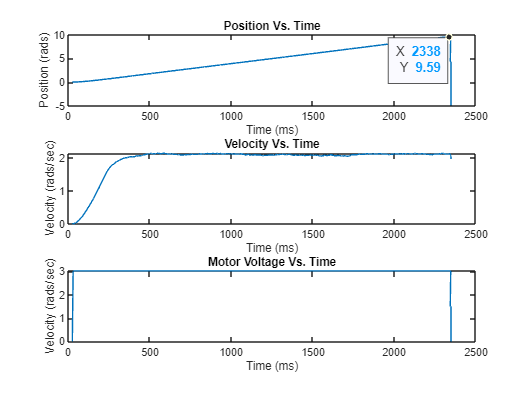

subplot(3,1,1);
plot(dataTable.time, dataTable.pos)
title('Position Vs. Time')
ylabel('Position (rads)')
xlabel('Time (ms)')

subplot(3,1,2);
% moving average filter
t = dataTable.time;
v = dataTable.vel;
windowSize = 40;
b = (1/windowSize) * ones(1, windowSize);
a = 1;
y = filter(b,a,v);
plot(t, y)
title('Velocity Vs. Time')
ylabel('Velocity (rads/sec)')
xlabel('Time (ms)')

subplot(3,1,3);
plot(dataTable.time, dataTable.motor)
title('Motor Voltage Vs. Time')
ylabel('Velocity (rads/sec)')
xlabel('Time (ms)')